
x_0 = -10;%initial condition
v_0 = 0;
dt = 0.1;%time step
t = 0:0.01:1;
target = 5;%set point
%PID settings
kp = 2;%proportional
ki = 0;%integral
kd = 1;%derivative

%initalize position and error arrays
x = ones(length(t),1).*x_0;
v = ones(length(t), 1).*v_0;
error = ones(length(t),1)*(target-x_0);%include inital error
i_err = 0;%start integral tracker

%system for constant current
c1 = 0.5;
c2 = 4;
m = 0.065%in kg

m = 0.0650

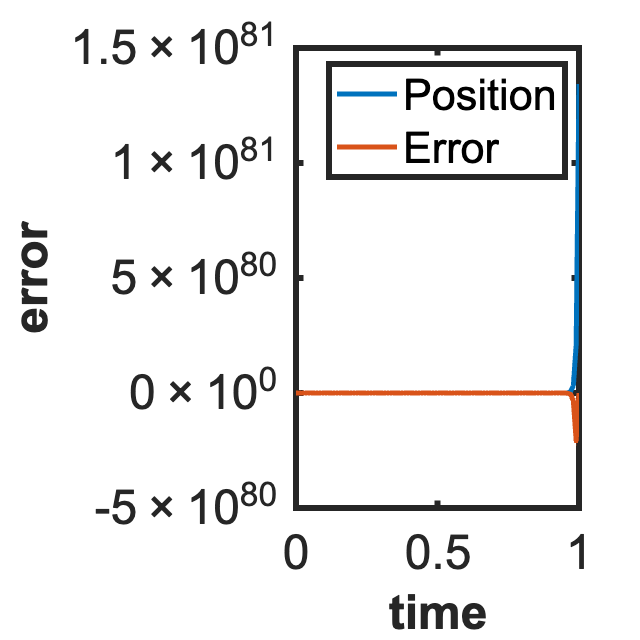

acc = @(position) (c1*position+c2)/m;%linear model

%main loop
for i = 2:length(t)-1
    error(i) = target-x(i);%update current error
    i_err = i_err+error(i)*dt;%keeps accumulating from 0, sum of all error so far times timestep
    d_err = (error(i)-error(i-1))/dt; %change in error
    x(i+1) = kp*error(i)+ki*i_err-d_err*kd;%compute control signal (directly related to output in this simulation)
    % x(i+1) = transfer(v(i));
end

plot(t,x, "DisplayName","Position");
xlabel("time");
ylabel("position");
hold on;
plot(t, error,"DisplayName","Error");
xlabel("time");
ylabel("error");

improvePlot;

hold off;
legend